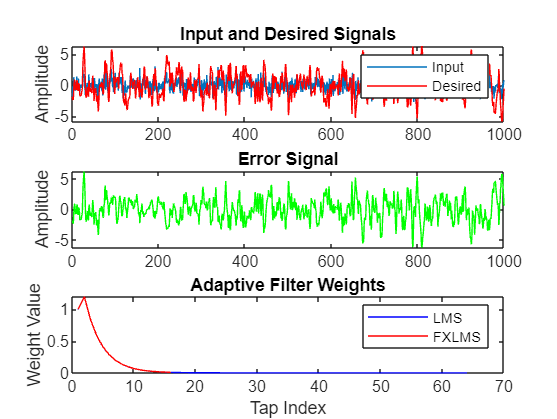

% Hybrid Adaptive Filter for Active Noise Control
clear all; close all; clc;

% Parameters
mu_lms = 0.01;      % Step size for LMS
mu_fxlms = 0.01;    % Step size for FXLMS
M = 64;             % Filter order for LMS
L = 16;             % Filter length for FXLMS

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Initialize weight vectors
w_lms = zeros(M,1);     % Filter weights for LMS primary path
w_ref = zeros(L,1);     % Filter weights for FXLMS reference path

% Buffers
x_buf_lms = zeros(M,1);
y_buf = zeros(length(d),1);
x_buf_fxlms = zeros(L,1);

% Main loop
for n = (max(M,L)+1):length(x)
    
    % LMS
    % Shift input buffer for LMS
    x_buf_lms = x(n:-1:n-M+1); 
    
    % FIR filter output for LMS primary path
    y_lms = w_lms'*x_buf_lms;
    
    % Error signal for LMS
    e_lms = d(n) - y_lms;
    
    % Update weight vector for LMS
    w_lms = w_lms + mu_lms * e_lms * x_buf_lms;
    
    % FXLMS
    % Shift input buffer for FXLMS reference path
    x_buf_fxlms = x(n:-1:n-L+1);
    
    % FIR filter output for FXLMS reference path
    y_ref = w_ref'*x_buf_fxlms;
    
    % Error signal for FXLMS
    e_fxlms = d(n) - y_ref;
    
    % Update weight vector for FXLMS
    w_ref = w_ref + mu_fxlms * e_fxlms * x_buf_fxlms;
    
    % Final estimate combining both LMS and FXLMS
    y = y_lms + y_ref;
    y_buf(n) = y;
end

% Plot results
figure;
subplot(3,1,1);
plot(x); hold on; plot(d,'r'); legend('Input','Desired');
ylabel('Amplitude');
title('Input and Desired Signals');

subplot(3,1,2);
plot(d-y_buf,'g'); 
ylabel('Amplitude');
title('Error Signal');

subplot(3,1,3);
plot(w_lms, 'b'); hold on; plot(w_ref, 'r');
ylabel('Weight Value');
xlabel('Tap Index');
legend('LMS', 'FXLMS');
title('Adaptive Filter Weights');